# Exercice 11 - Optimisation multi-objectifs 

## Données

Un dispatcher d'énergies dispose de 5  centrales thermiques de différentes technologiques qui produisent de l'électricité. Il est capable de prédire le coût de chaque centrale à partir d'une relation de type : 


$$C_I \left(P_I \right)=a_I {\left(P_I \right)}^2 +b_I {\left(P_I \right)} +c_I$$


$C_I$ est le coût de production selon la puissance produite ($P_I$) pour l'unité *I*. 

Chaque centrale a des limites de production : $P_{I,\min } {\le P}_I \le P_{I,\max }$

Chaque centrale produit des émissions polluantes. Le dispatcher dispose de relation pour estimer la quantité totale ($T_I$) de polluants produite en kg/j par chaque centrale en fonction de sa puissance thermique ($P_I$) :  


$$T_I \left(P_I \right)=d_I {\left(P_I \right)}^2 +e_I {\left(P_I \right)} +f_I$$


Les données des 5 centrales sont disponibles dans le fichier `data_Exercice11.mat` (`load data_Exercice11`): coefficients `A, B, C, D, E` et `F` des deux formules ci-dessus ainsi que `Pmin` et `Pmax`. 

Toutes les puissances sont exprimées en MW.

clear


## Partie 1: Optimisation économique 

% Demande en énergie
Demande = 400;
% variables: puissance de chaque centrale 

load data_Exercice11
% variables: puissance de chaque centrale 
% Définition de la fonction objective
f = @(x) x.^2*A + x*B + sum(C);

% contraintes inégalités linéaires
Aineq = [];
bineq = [];

% contraintes égalités linéaires 
Aeq =ones(1,length(Pmin));
beq=Demande;

% Définition des bornes
lb = Pmin;
ub = Pmax;

opt = optimset('Display','iter');
x0 = [50 ; 100; 100; 100 ; 45]';

[x1,fval,flag,out,lambda,grad]=fmincon(f,x0,Aineq,bineq,Aeq,beq,lb,ub,'', opt);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.442238e+05    5.000e+00    3.137e+02
    1      12    1.351442e+05    4.779e+00    2.278e+02    2.077e+01
    2      18    1.330398e+05    3.999e+00    1.671e+02    9.399e+00
    3      24    1.315688e+05    1.180e+00    9.653e+01    3.446e+01
    4      30    1.315348e+05    1.176e+00    9.557e+01    2.618e-01
    5      36    1.314239e+05    1.198e-01    4.532e+01    1.587e+01
    6      42    1.314210e+05    5.866e-02    4.028e+01    7.333e-01
    7      48    1.314417e+05    2.114e-02    2.805e+00    7.597e-01
    8      54    1.314550e+05    0.000e+00    2.669e-01    1.585e-01
    9      60    1.314550e+05    0.000e+00    1.533e-04    5.141e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

disp (flag)

     1



disp (fval)

   1.3146e+05



disp (x1)

  102.8442   90.0000   76.7303   77.4255   53.0000



**Graphique : Evolution de la puissance de chaque centrale en fonction de la demande**


Demande1= 300:75:975;

% Le maximum de puissance que peut fournir les 5 centrales cumulées est de 998 MW, on plafonne donc la demande en puissance à une valeur inférieur à
% 998

Centrale = 5;
P = ones(Centrale, length(Demande1));% P est une matrice de 5 lignes, car 5 centrales et 10 colonnes, car 10 demandes 
    for j = 1:length(Demande1)
        beq = Demande1(j);
        opt = optimset('Display','iter');
        x0 = [50 ; 100; 100; 100 ; 45]';
        options = optimoptions('fmincon','Display','iter');
        [x,fval,flag,out,lambda,grad]=fmincon(f,x0,Aineq,bineq,Aeq,beq,lb,ub,'', opt);
        P(:,j)= P(:,j).*x';
    end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.442238e+05    9.500e+01    3.137e+02
    1      12    1.314378e+05    9.043e+01    2.257e+02    2.281e+01
    2      18    1.258125e+05    8.305e+01    1.740e+02    4.751e+00
    3      24    1.128349e+05    6.380e+01    1.754e+02    1.458e+01
    4      30    1.099730e+05    6.001e+01    1.655e+02    6.195e+00
    5      36    1.079847e+05    5.643e+01    1.563e+02    2.719e+00
    6      42    1.044131e+05    4.941e+01    1.559e+02    6.750e+00
    7      48    1.044001e+05    4.939e+01    1.559e+02    2.233e-02
    8      54    8.815953e+04    0.000e+00    1.486e+02    3.682e+01
    9      60    8.813204e+04    0.000e+00    1.777e+01    9.965e-01
   10      66    8.809402e+04    0.000e+00    1.792e-01    3.315e+00
   11      72    8.809396e+04    0.000e+00    2.897e-04    5.003e-04



disp (P)

   37.6701   88.0000  122.5082  145.7039  168.8996  192.0953  206.0000  206.0000  206.0000  206.0000
   90.0000   90.0000   90.9851  108.1671  125.3491  142.5310  162.7947  187.6699  224.3843  261.6045
   68.0000   68.0000   91.2962  108.4782  125.6602  142.8422  163.1056  187.9810  189.0000  189.0000
   76.0000   76.0000   92.2104  109.6508  127.0912  144.5315  165.0997  190.3491  227.6157  265.3955
   28.3299   53.0000   53.0000   53.0000   53.0000   53.0000   53.0000   53.0000   53.0000   53.0000



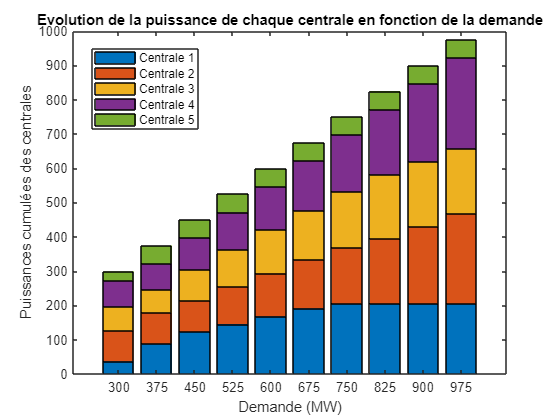

figure
bar(Demande1,P,'stacked')
xlabel('Demande (MW)')
ylabel('Puissances cumulées des centrales')
title(sprintf(['Evolution de la puissance de chaque centrale en fonction de la demande']))
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

** Graphique : Evolution du coût optimal en fonction de la demande**  

Demande1= 300:75:975;

C = ones(1, length(Demande1));
    for j = 1:length(Demande1)
        beq = Demande1(j);
        opt = optimset('Display','iter');
        x0 = [50 ; 100; 100; 100 ; 45]';
        options = optimoptions('fmincon','Display','iter');
        [x,fval,flag,out,lambda,grad]=fmincon(f,x0,Aineq,bineq,Aeq,beq,lb,ub,'', opt);
        C(j) = C(j).*fval;
    end 

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.442238e+05    9.500e+01    3.137e+02
    1      12    1.314378e+05    9.043e+01    2.257e+02    2.281e+01
    2      18    1.258125e+05    8.305e+01    1.740e+02    4.751e+00
    3      24    1.128349e+05    6.380e+01    1.754e+02    1.458e+01
    4      30    1.099730e+05    6.001e+01    1.655e+02    6.195e+00
    5      36    1.079847e+05    5.643e+01    1.563e+02    2.719e+00
    6      42    1.044131e+05    4.941e+01    1.559e+02    6.750e+00
    7      48    1.044001e+05    4.939e+01    1.559e+02    2.233e-02
    8      54    8.815953e+04    0.000e+00    1.486e+02    3.682e+01
    9      60    8.813204e+04    0.000e+00    1.777e+01    9.965e-01
   10      66    8.809402e+04    0.000e+00    1.792e-01    3.315e+00
   11      72    8.809396e+04    0.000e+00    2.897e-04    5.003e-04



disp (C)

   1.0e+05 *

    0.8809    1.1651    1.6631    2.2816    3.0045    3.8317    4.7671    5.8452    7.1088    8.5986



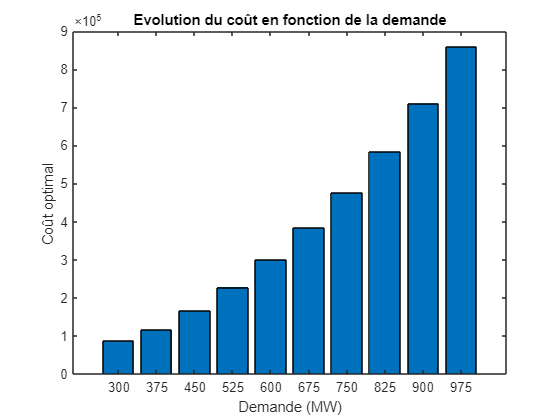

figure
bar(Demande1,C,'stacked')
xlabel('Demande (MW)')
ylabel('Coût optimal ')
title(sprintf(['Evolution du coût en fonction de la demande']))

## Partie 2: Optimisation environnementale

Nous allons ici chercher à minimiser les émissions polluantes des centrales. La quantité d'émission polluante est directement liée  à la puissance émise par les centrales. 

load data_Exercice11
% Nous avons la fonction objectif suivante: 

fenv = @(x) x.^2*D + x*E + sum(F);

% contraintes inégalités linéaires
Aineq = [];
bineq = [];

% contraintes égalités linéaires
Aeq =ones(1,length(Pmin));
Demande = 400; 
beq=Demande;

% Définition des bornes
lb = Pmin;
ub = Pmax;

opt = optimset('Display','iter');
x0 = [50 ; 100; 100; 100 ; 45]';
options = optimoptions('fmincon');
% options = optimoptions('fmincon','Display','iter');
[x2,fval,flag,out,lambda,grad]=fmincon(fenv,x0,Aineq,bineq,Aeq,beq,lb,ub,'', opt);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.099177e+05    5.000e+00    5.025e+02
    1      12    9.030559e+04    4.763e+00    2.661e+02    3.271e+01
    2      18    8.956568e+04    4.635e+00    2.524e+02    2.299e+00
    3      24    8.758020e+04    4.213e+00    2.448e+02    5.842e+00
    4      30    8.668119e+04    3.937e+00    2.406e+02    3.036e+00
    5      36    8.663058e+04    3.854e+00    7.194e+01    8.867e-01
    6      44    8.659128e+04    2.890e+00    5.105e+01    5.955e+00
    7      50    8.712216e+04    5.684e-14    3.547e+01    1.290e+01
    8      56    8.709100e+04    0.000e+00    2.596e+00    5.008e+00
    9      62    8.708941e+04    0.000e+00    4.302e-01    1.066e+00
   10      68    8.708940e+04    0.000e+00    2.637e-02    6.369e-02
   11      74    8.708940e+04    5.684e-14    4.416e-04    3.100e-03



disp(flag)

     1



disp(fval)

   8.7089e+04



disp (x2)

   71.6220   90.0000   68.0000  129.7628   40.6152



**Analyse des résultats **

Pour une demande de 400 MW, nous obtenions, en optimisant le coût: x1 = [102.8442 90.000 76.7303 77.4255 53.000] 

Ici, nous avons, en optimisant les émissions polluantes:  x2 = [71.6220  90.000  68.000  129.7628  40.6152] 

**Validation** sum (x1) = sum (x2) => **OK cohérent **

 En optimisant les émissions polluantes les centrales 1, 3 et 5 diminuent leur production. Cette diminution de la production est compensée par une hausse de production des centrales 2 et 4. Nous pouvons émettre l'hypothèse que ce sont les centrales 1, 3 et 5 qui émettent le plus de pollution. 

Résumons cette analyse par un graphique de comparaison des répartitions de puissances suivant l'optimisation choisie à une demande fixée de 40 MW: 

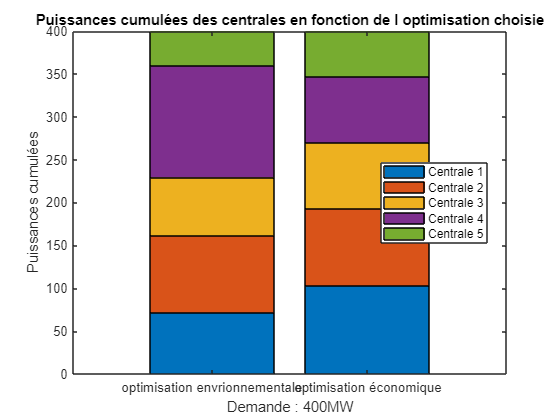

Puissances=[x2 ; x1];
Demandefixe=categorical({'optimisation envrionnementale','optimisation économique'});
figure
bar(Demandefixe,Puissances,'stacked');
xlabel('Demande : 400MW')
ylabel('Puissances cumulées')
title(sprintf(['Puissances cumulées des centrales en fonction de l optimisation choisie']))
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

**Validation:** 

Force est de constater que les centrales 1, 3 et 5 sont plus rentables mais aussi plus polluantes. C'est l'inverse pour les centrales 2 et 4: elles sont moins rentables et moins polluantes. 

## Partie 3 : optimisation multicritère 

Méthode des pondérations

load data_Exercice11
% Nous avons la fonction objectif suivante: 

% fmulti= @(x) w1*(x.^2*A + x*B + sum(C)) + w2*(x.^2*D + x*E + sum(F)); w1
% et w2 sont les poids pour chaque fontion

% contraintes inégalités linéaires
Aineq = [];
bineq = [];

% contraintes égalités linéaires
Aeq =ones(1,length(Pmin));
Demande = 400; 
beq=Demande;

% Définition des bornes
lb = Pmin;
ub = Pmax;

x0 = [50 ; 100; 100; 100 ; 45]';
pareto=[];
f1val=[];
f2val=[];
for i=0:10
    w1=i/10;
    w2=1-w1;
    options = optimoptions('fmincon','Display','iter','Diagnostics','on');
    fmulti= @(x) w1*(x.^2*A + x*B + sum(C)) + w2*(x.^2*D + x*E + sum(F));
    [x3,fval3,flag,out]=fmincon(fmulti,x0,Aineq,bineq,Aeq,beq,lb,ub,'',options);
    pareto = [pareto fval3];
    f1val=[f1val f(x3)];
    f2val=[f2val fenv(x3)];
end

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)w1*(x.^2*A+x*B+sum(C))+w2*(x.^2*D+x*E+sum(F))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.099177e+05    5.000e+00    5.025e+02
    1      12    9.030559e+04    4.763e+00    2.661e+02    3.271e+01
    2      

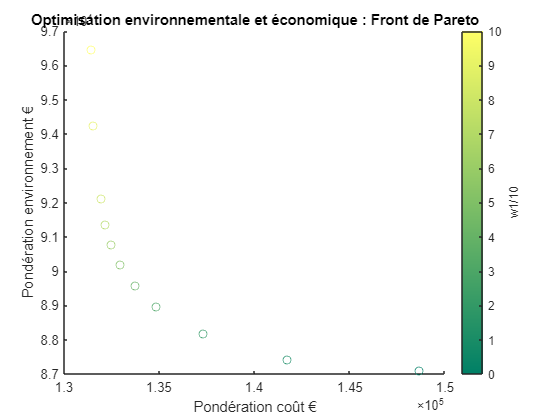


Z=0:10;
scatter(f1val,f2val,[],Z)
colormap summer
c = colorbar;
c.Label.String = 'w1/10'; 
xlabel('Pondération coût €')
ylabel('Pondération environnement €')
title('Optimisation environnementale et économique : Front de Pareto')

**Interprétation des résultats **

**Le front de pareto nous permet de visualiser l'optimum économique et environnemental environ du poids de chaque critère. **

## Conclusions

A partir de l'ensemble des résultats obtenus, quelles sont vos conclusions générales sur l'optimum de fonctionnement ?  

En conclusion l'optimium de fonctionnemnet nous permet d'agir sur les critères de notre choix, ici : environnement vs économie. 